load fisheriris.mat meas species

%tm=array2table(meas);

v=var(meas)

v =     0.6857    0.1900    3.1163    0.5810


measScale=(meas-mean(meas))./range(meas)

measScale =    -0.2065    0.1844   -0.3997   -0.4164
   -0.2620   -0.0239   -0.3997   -0.4164
   -0.3176    0.0594   -0.4166   -0.4164
   -0.3454    0.0178   -0.3827   -0.4164
   -0.2343    0.2261   -0.3997   -0.4164
   -0.1231    0.3511   -0.3488   -0.3331
   -0.3454    0.1428   -0.3997   -0.3747
   -0.2343    0.1428   -0.3827   -0.4164
   -0.4009   -0.0656   -0.3997   -0.4164
   -0.2620    0.0178   -0.3827   -0.4581


vs=var(measScale)

vs =     0.0529    0.0330    0.0895    0.1009


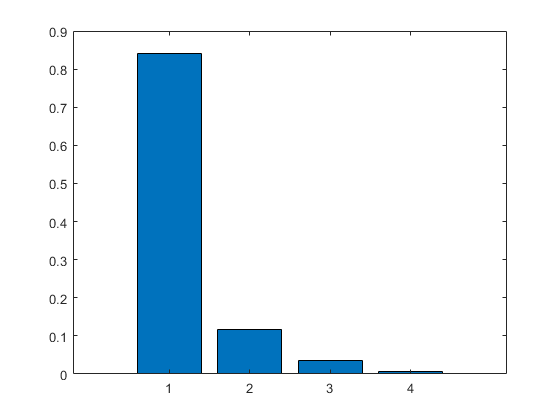

[P,S,V]=pca(measScale);
vnorm=V/sum(V);
bar(vnorm)

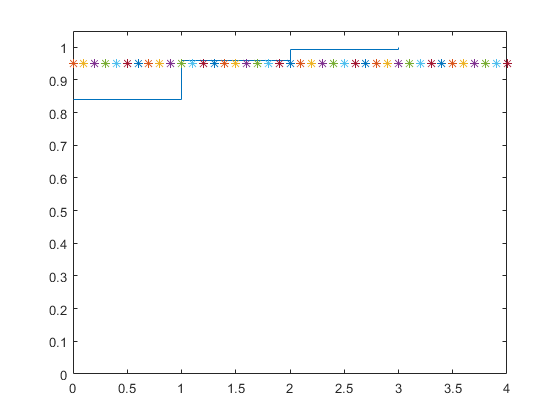

stairs(0:3.9,cumsum(vnorm))
xlim([0 4])
ylim([0 1.05])
hold on
x=0:0.1:5;
plot(x,0.95,'*')

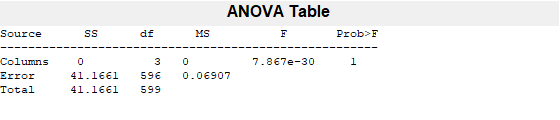

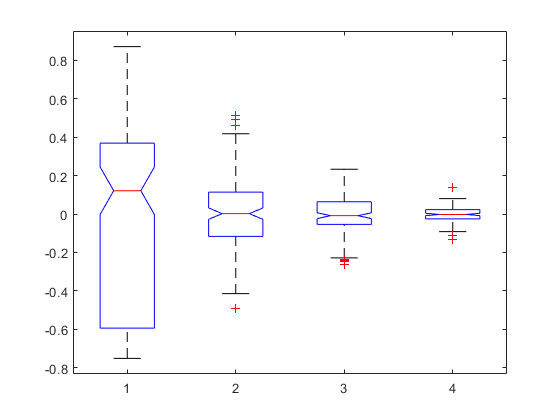

ans = 1

anova1(S)

reducedData = S(:, 1:2)

reducedData =    -0.6307    0.1076
   -0.6229   -0.1043
   -0.6695   -0.0514
   -0.6542   -0.1029
   -0.6488    0.1335
   -0.5353    0.2896
   -0.6565    0.0107
   -0.6258    0.0571
   -0.6756   -0.2007
   -0.6456   -0.0672


met="silhouette"

met = "silhouette"

va = evalclusters(reducedData,"kmeans", met, "KList", 2:5)

va =   SilhouetteEvaluation with properties:

    NumObservations: 150
         InspectedK: [2 3 4 5]
    CriterionValues: [0.8313 0.7435 0.7043 0.6250]
           OptimalK: 2


[clst,cen]=kmeans(reducedData,3,"Replicates",5)

clst =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


cen =     0.5567    0.1037
   -0.6184    0.0686
    0.1510   -0.1225


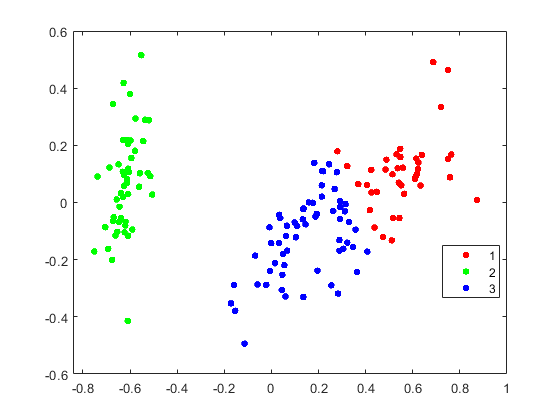

% Clustered data  clst is the output from kmeans
gscatter(reducedData(:,1), reducedData(:,2), clst)

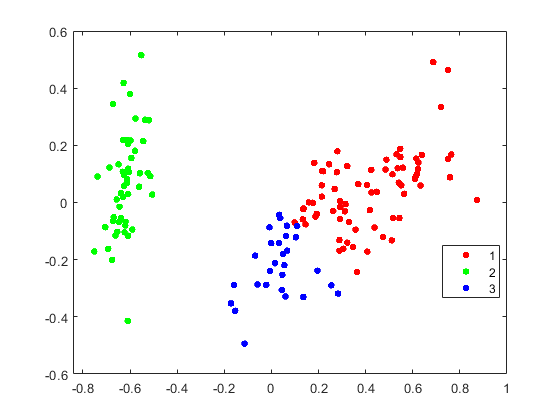

clst=kmeans(measScale,3,"Distance","cosine","Replicates",7);
% Clustered data  clst is the output from kmeans
gscatter(reducedData(:,1), reducedData(:,2), clst)